# 用脚本将数据导入SDI绘图示例

- 本文以表格形式的数据为例，其他形式的数据可以先转换成表格形式再导入SDI绘图。

- 表格形式的数据又可以分为带时间轴的和不带时间轴的，由于**SDI通常用于Simulink仿真查看时变信号波形，天生面向的是时间序列（timeseries）**，所以对于不带时间轴的数据，必须人为补充时间轴，才能导入SDI，并通过脚本绘图。

- **注：**在SDI中其实是可以画X-Y二维坐标图的，但是基础数据源也必须带时间轴，且不支持脚本操作，暂时只能在SDI界面中手动勾选。

## *****一种GUI操作方式**

- 除了脚本导入SDI绘图的方式，如果手头已经有了一份格式规范的带时间轴的Excel表格形式数据记录，也可以直接在MATLAB命令行中使用下述指令调出SDI界面，导入Excel表格文件，就可以勾选绘图，效率更高。**对于自主可控的数据记录，设定好记录格式，可以实现高效分析数据。**

- 格式规范的Excel表格文件示例如下，**重点：第一列是时间轴，表头为time，数值单位为秒**，其他列代表单独的信号，表头是信号名称。

        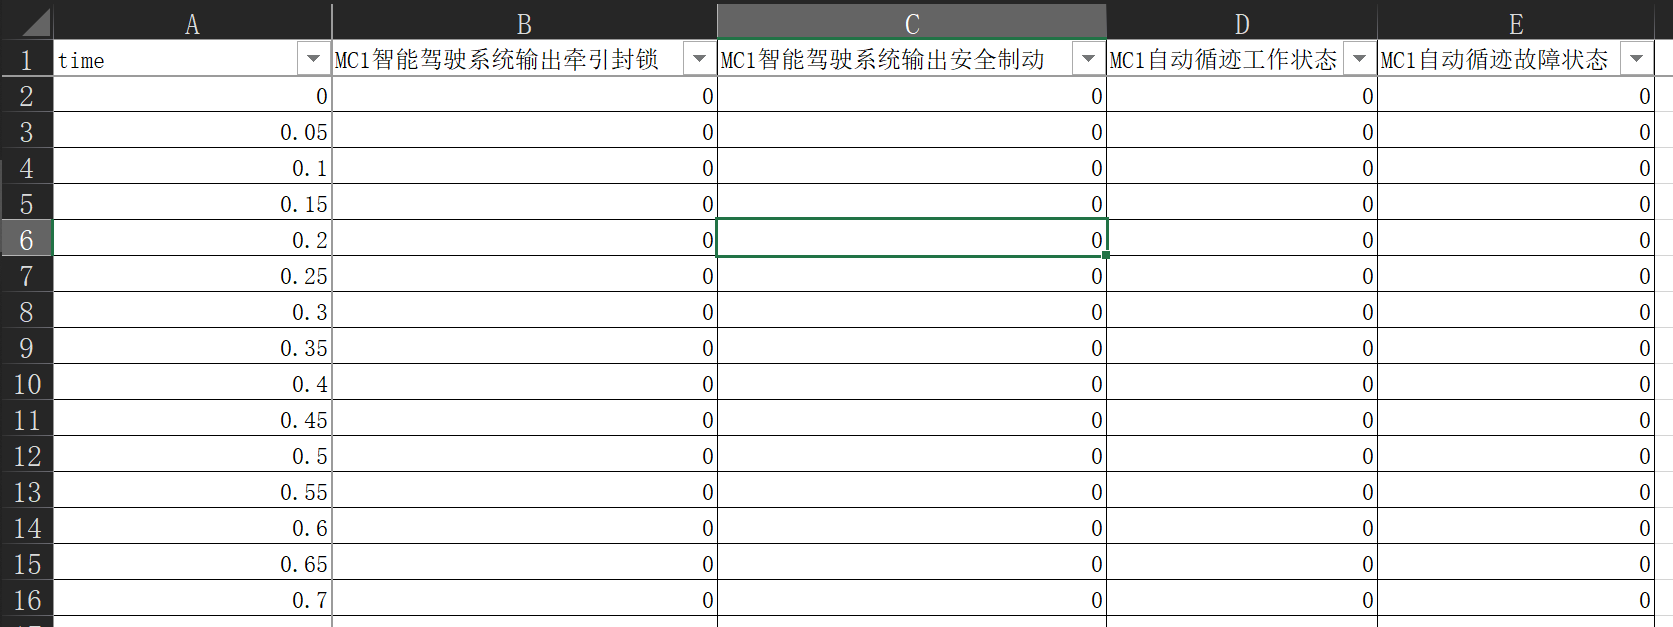

- SDI中直接导入格式规范的Excel表格文件后的效果如下，可以看到信号名称就是表格里的表头。

        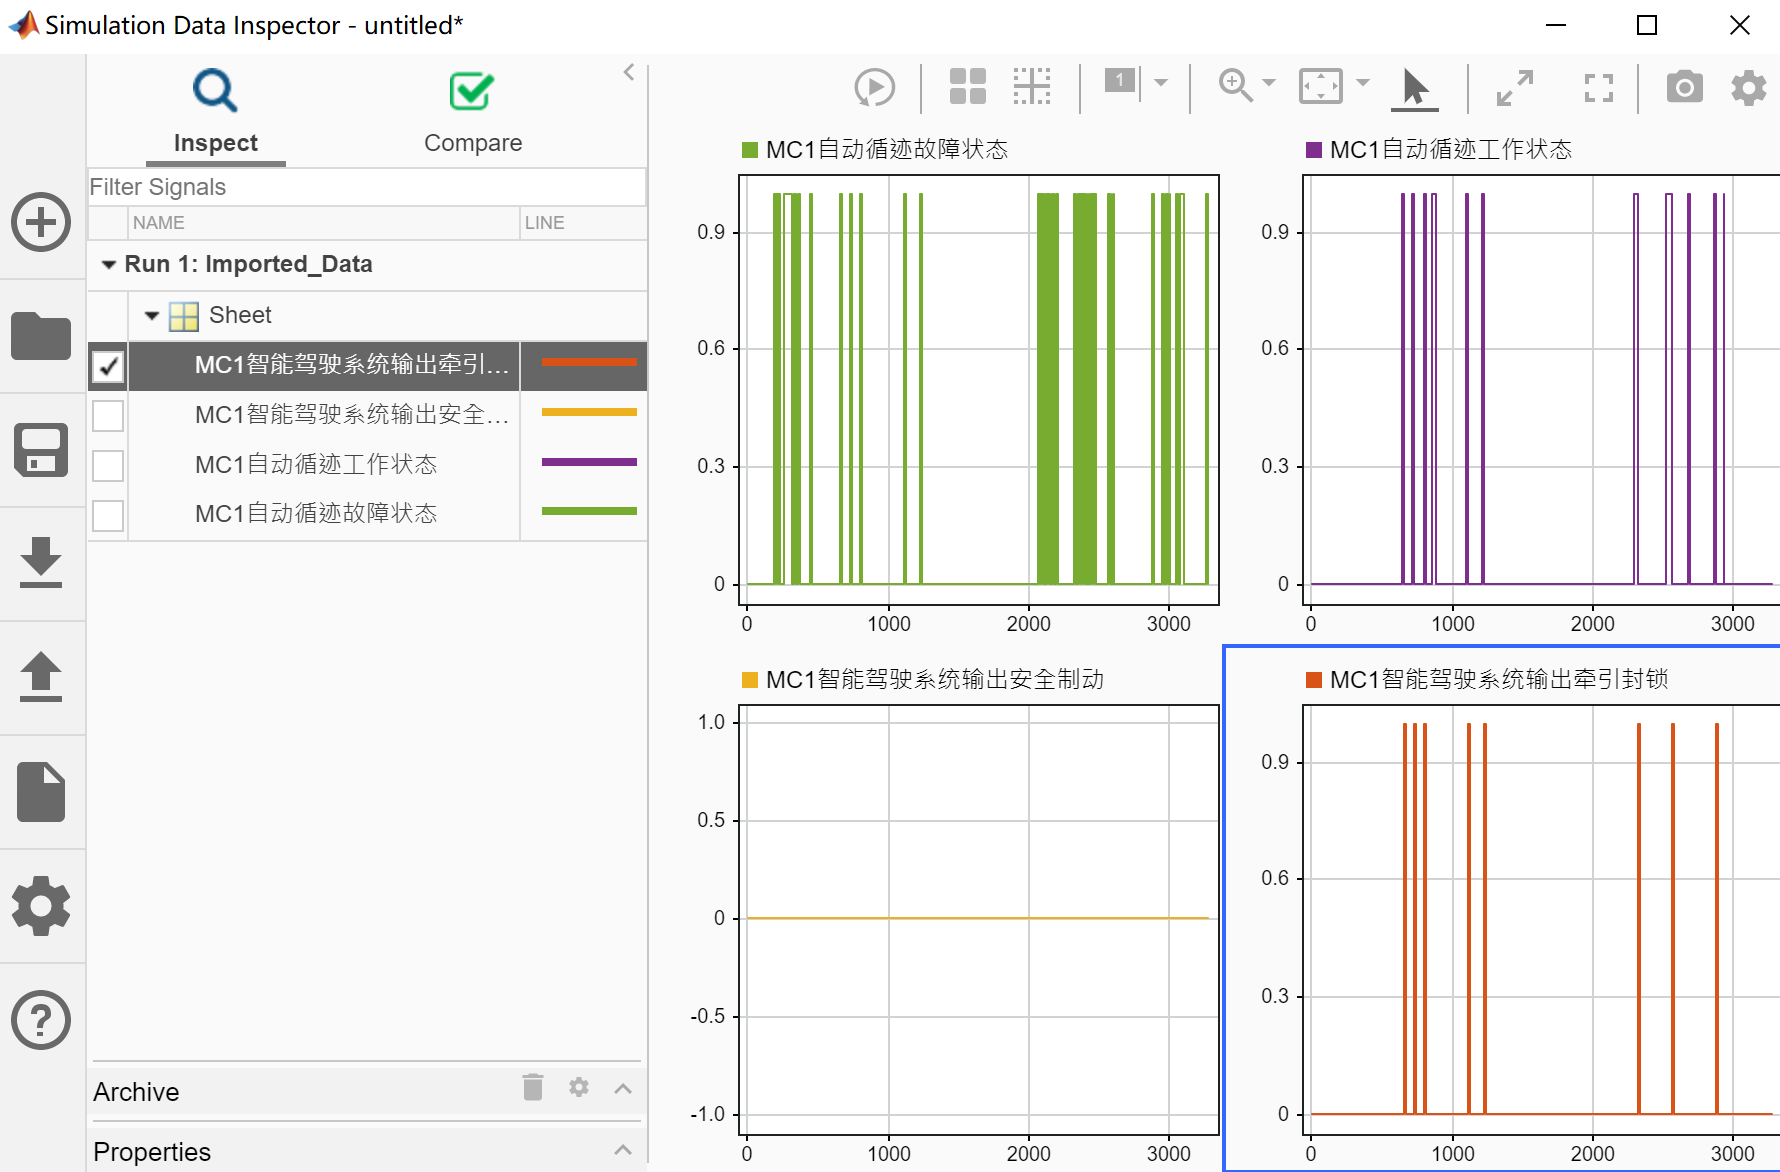

- 下面分章节介绍整个脚本流程，由于本文没有使用现场真实数据，则构造数据时也需要补充时间轴，对于不带时间轴的数据可以参照初始化章节中的思路补充时间轴。

## 1.初始化

- 以两个正弦信号为例。

clc;
clearvars;
close all;


- 构建时间轴，**通常SDI以秒为时间单位，支持小数**。假设模拟一段30s长度的现场循迹控制软件数据记录，控制周期50ms，则时间轴间隔0.05s。

- **注：**一般的真实数据记录时间戳可能是年月日时分秒等特殊格式，需要先转换成相对秒数，得到时间轴数据，才能导入SDI绘图。MATLAB自带的相关时间格式转换接口如下，供参考。

t = transpose(0 : 0.05 : 30);


- 正弦信号1：$y_1 =\sin \left(2t+\frac{\pi }{4}\right)$

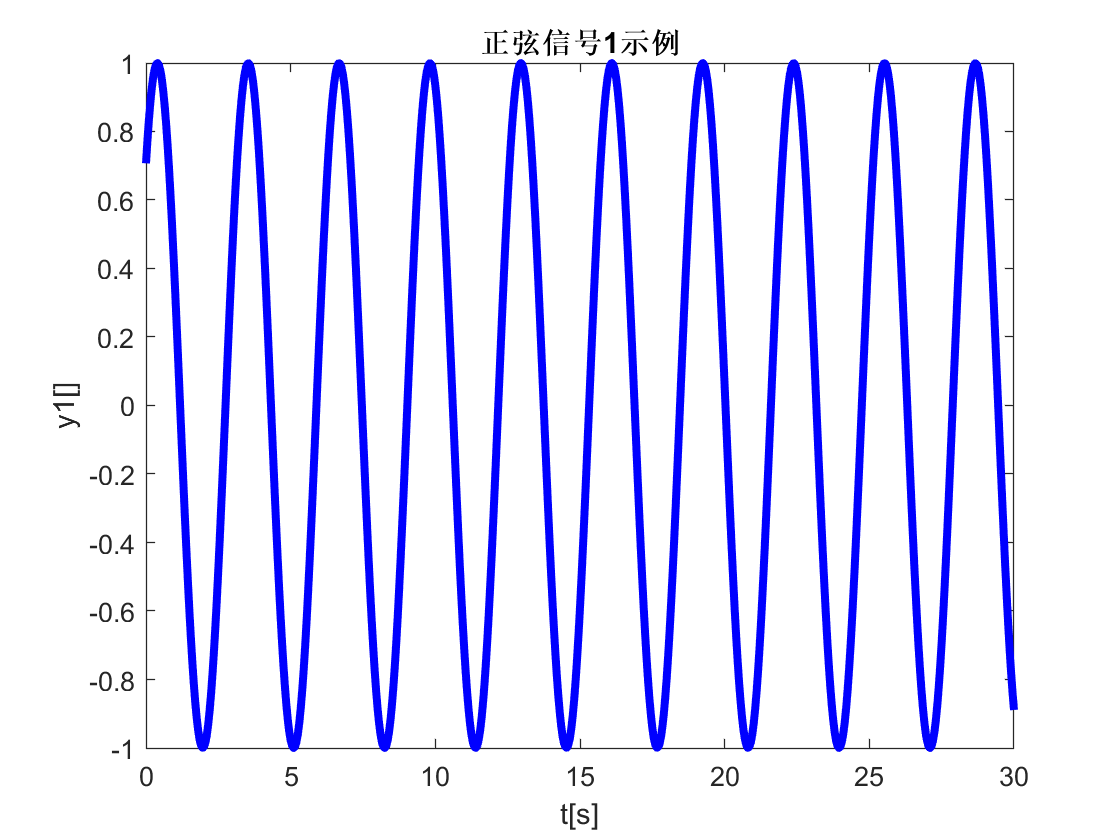

y1 = sin(2 * t + pi/4);

% plot绘图示意
figure;
plot(t, y1, 'b', 'LineWidth', 3);
xlabel('t[s]');
ylabel('y1[]');
title('正弦信号1示例');

- 正弦信号2：$y_2 =2\sin \left(2t+\frac{\pi }{2}\right)$

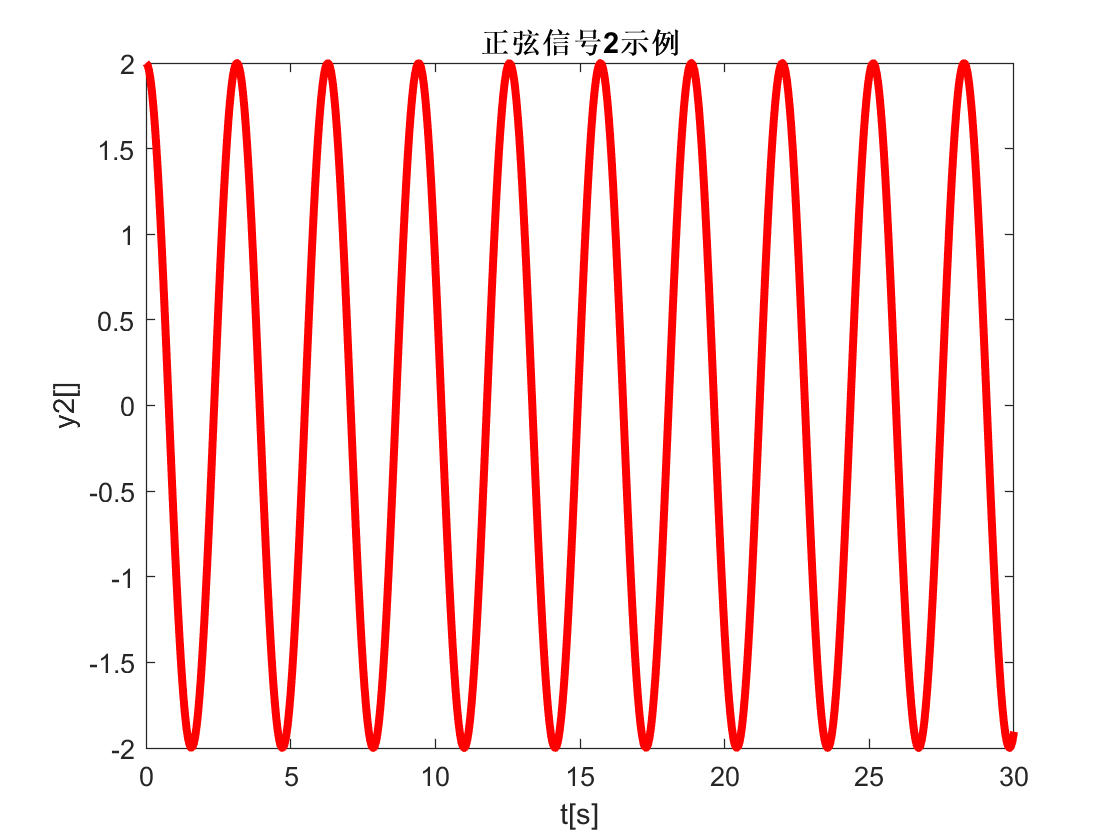

y2 = 2 * sin(2 * t + pi/2);

% plot绘图示意
figure;
plot(t, y2, 'r', 'LineWidth', 3);
xlabel('t[s]');
ylabel('y2[]');
title('正弦信号2示例');

- 合成表格形式（table）数据集，如果是真实的表格形式数据记录，则可以使用以下接口导入table。

example_data = table(t, y1, y2, 'VariableNames', {'时间轴', 'y1', 'y2'});


- 调用MATLAB自带接口清空历史SDI数据，如果希望保留之前的SDI绘图及数据源，可以不执行清空SDI操作。

Simulink.sdi.clear;
Simulink.sdi.clearPreferences;


## 2.创建Simulink.sdi.Run对象的一个实例作为SDI的数据容器

- `调用`MATLAB自带`接口创建Run对象实例。`

example_run = Simulink.sdi.Run.create;


- `配置`MATLAB自带接口`属性。`

% 数据名称
example_run.Name = '数据名称1';

% 数据备注描述信息
example_run.Description = '数据备注描述信息';


## 3.创建Simulink.SimulationData.Dataset对象的一个实例作为数据源

- `调用`MATLAB自带`接口，配置对象属性。`

SDI_data_source = Simulink.SimulationData.Dataset;
SDI_data_source.Name = '数据名称2';


- 获取数据集表格表头（信号名称）并剔除时间轴。

signal_namelist_original = example_data.Properties.VariableNames;
signal_namelist = signal_namelist_original(~ismember(signal_namelist_original, '时间轴'));


- 遍历数据集中除时间轴外的每个信号，`调用`MATLAB自带`接口`构造timeseries对象实例，并添加到Dataset对象实例中。

for index = 1 : size(signal_namelist, 2)
    temp_timeseries = timeseries(example_data.(signal_namelist{index}), ...
        example_data.('时间轴'), 'Name', signal_namelist{index});
    SDI_data_source = SDI_data_source.addElement(temp_timeseries);
end


## 4.将Dataset对象实例（数据源）加入Run对象实例（数据容器）中

- 调用MATLAB自带接口实现数据导入SDI。

example_run.add(SDI_data_source);


## 5.切分SDI子图区域

- 调用MATLAB自带接口将SDI绘图区域分割成2×2的4幅子图。

Simulink.sdi.setSubPlotLayout(2, 2);


## 6.设置曲线颜色、线形

- **注：如无特殊要求，可以省略本章节操作，使用自动设置的曲线颜色、线形，或者在SDI界面中手动设置。**

- 为了全面介绍相关操作，假设将y1信号曲线颜色设置为海军蓝（#000080），线形设置为虚线（`--`）。

- `调用`MATLAB自带接口根据信号名称'y1'获取y1信号对象实例。

y1_signal = getSignalsByName(example_run, 'y1');


- `调用`MATLAB自带接口将16进制颜色码转换为RGB值(0~255，1×3向量)，再归一化到0~1之间。

normalized_color_value = hex2dec(["00" "00" "80"]) / 255;


- `调用`MATLAB自带接口属性LineColor设定y1信号曲线颜色为海军蓝（#000080）。

y1_signal.LineColor = normalized_color_value;


- 调用MATLAB自带接口属性LineDashed设定y1信号曲线线形为虚线（`--`）。

y1_signal.LineDashed = '--';


## 7.在指定SDI子图上显示指定信号曲线

y2_signal = getSignalsByName(example_run, 'y2');


- 调用MATLAB自带接口在第1行第1列的子图上同时显示y1、y2信号曲线。

plotOnSubPlot(y1_signal, 1, 1, true);
plotOnSubPlot(y2_signal, 1, 1, true);


- 调用MATLAB自带接口在第2行第1列的子图上显示y1信号曲线。

plotOnSubPlot(y1_signal, 2, 1, true);


- 调用MATLAB自带接口在第2行第2列的子图上显示y2信号曲线。

plotOnSubPlot(y2_signal, 2, 2, true);


## 8.打开SDI界面查看数据波形

- 调用MATLAB自带接口。

Simulink.sdi.view;


- 效果如下。